ans =    -0.0682   -0.0691   -0.0719   -0.0719   -0.8345    0.0277   -0.1125   -0.0719   -0.2023    0.1191   -0.0656   -0.0700   -0.0719   -0.0719    0.9693   -0.0517   -0.7238   -0.0720   -0.6535    2.2476   -0.0811
   -0.2366    0.1278   -0.1274   -0.1274   -0.1324   -1.1793   -0.0420   -0.1318   -0.1002   -0.1312   -0.0797   -0.3885   -0.1274   -0.1274   -0.1271    0.2882    2.1512   -0.1273    0.8373   -0.0960   -0.1227
   -0.0588   -0.0578   -0.0626   -0.0626   -0.8862    0.0418   -0.1027   -0.0625   -0.1947    0.1338   -0.0558   -0.0616   -0.0626   -0.0626    0.9979   -0.0401   -0.7560   -0.0626   -0.6804    2.1684   -0.0724
    0.2314   -0.1365    0.0612   -0.1167    0.2528   -0.7006    0.0161    0.0607   -0.0490    0.1302   -0.0845    0.2737    0.0600    0.2338   -0.0329    0.8475   -1.2361    0.0609   -0.7334    0.8174    0.0440
   -0.2234   -0.0801   -0.4059   -0.2161   -0.2182   -0.2226   -0.1389   -0.2262   -0.1808   -0.2182   -0.2241   -0.3501   -0.0464   -0.2192   -0.2231

Nk = 1200

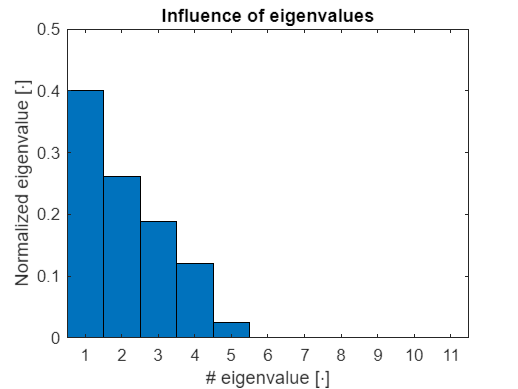

sumOfEig = 0.9719

clc
clear
load("MatlabData/trainingData_OG.mat")
load("MatlabData/ValidationData_OG.mat")
trainingData(:,12) = [];
trainingData(:,11) = [];
trainingData(:,2) = [];
validationData(:,12) = [];
validationData(:,11) = [];
validationData(:,2) = [];

D = 4;
Nk = length(trainingData)/21;
% Reduce
[W muw] = LDA_reduce(D, trainingData, trainingLabel, Nk);

y = W.' * trainingData.';

mu =    -0.5017    0.4621    0.1309   -0.1605   -0.4692   -0.4046    0.1536   -0.2660   -0.4724    0.3206    0.0048   -0.5559   -0.7339   -0.2773    0.3993    0.1566    0.6772   -0.2805   -0.5489    1.0841   -0.2637
   -0.2731    0.1890    0.0932    0.8706   -1.1319    1.4149   -0.0057    0.0954    0.1362   -0.5702    0.5586   -0.0706    0.0697   -0.5219    1.1772   -1.2466   -0.1159    0.0982   -0.1378   -0.4140    0.1227
    1.3152    0.0948    0.9680    0.2311    1.0566   -0.7556    0.4562    1.0143    0.8943    0.4638    0.3998    1.3238    0.9100    1.3436   -0.5358    1.1617   -1.3166    1.0009   -0.6911   -1.1206    0.9786
   -0.5404   -0.7459   -1.1921   -0.9411    0.5444   -0.2548   -0.6041   -0.8436   -0.5581   -0.2141   -0.9633   -0.6973   -0.2458   -0.5444   -1.0406   -0.0717    0.7553   -0.8186    1.3777    0.4505   -0.8376


cov =     0.0893    0.0069    0.0119   -0.1082    0.1897   -0.0040   -0.0819   -0.1038    0.0683    0.0445   -0.0552   -0.0577    0.1660    0.0399   -0.0533   -0.1526    0.0072   -0.0051    0.0008   -0.0028    0.0321   -0.0027   -0.0386    0.0093    0.3681    0.1559   -0.2762   -0.2478    0.1352    0.0324   -0.0211   -0.1464    0.1863    0.0301   -0.0100   -0.2065    0.2833    0.1084   -0.1321   -0.2595    0.2171    0.0329   -0.1322   -0.1179    0.0721    0.0049    0.0003   -0.0773    0.1470    0.0069
    0.0069    0.2331   -0.0848   -0.1552   -0.0040    0.6639   -0.3975   -0.2624    0.0445    0.2667   -0.1901   -0.1210    0.0399    0.3153   -0.3208   -0.0345   -0.0051    0.0085    0.0088   -0.0122   -0.0027    0.0025    0.0073   -0.0071    0.1559    0.6510   -0.5538   -0.2531    0.0324    0.4463   -0.2605   -0.2182    0.0301    0.5718   -0.3114   -0.2905    0.1084    0.6089   -0.4306   -0.2867    0.0329    0.4804   -0.3429   -0.1705    0.0049    0.1749   -0.0736   -0.1062    0.0069   

prior =     0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476    0.0476


Error using mvnpdf
SIGMA must be a square, symmetric, positive definite matrix.

Error in LDA>Calculate_Probabilit (line 104)
       P(:,i) = mvnpdf(data.', mu(:,i).', cova(:,i*D-(D-1):i*D))*prior(i);

function [W mu] = LDA_reduce(D, train, trainLabel, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(train(trainLabel == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(train);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (train(find(trainLabel==j),:)' - mu(j,:)') * (train(find(trainLabel==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';
    (mu(1:21,:)' - mu(22,:)')
    Nk
    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');
    
    bar(linspace(1,11,11),B/sum(B),1)
    xlim([0.5,11.5])
    title("Influence of eigenvalues")
    ylabel("Normalized eigenvalue [⋅]")
    xlabel("# eigenvalue [⋅]")
    saveas(gcf,'Images/LDA_Eig_Bar','epsc')
    sumOfEig = sum(B(1:D))/sum(B)
    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end